ans = 2.9957

sys =
 
               1
  ---------------------------
  0.08333 s^2 + 0.1 s - 2.455
 
Continuous-time transfer function.



G =
 
          0.131 s^3 + 1.074 s^2 - 2.758 s - 27.01
  --------------------------------------------------------
  0.006944 s^4 + 0.1476 s^3 + 0.6746 s^2 - 3.249 s - 20.98
 
Continuous-time transfer function.



p =    4.8608 + 0.0000i
 -10.0286 + 1.4028i
 -10.0286 - 1.4028i
  -6.0608 + 0.0000i


z =     4.8608
   -7.0000
   -6.0608


alpha = 0.4559

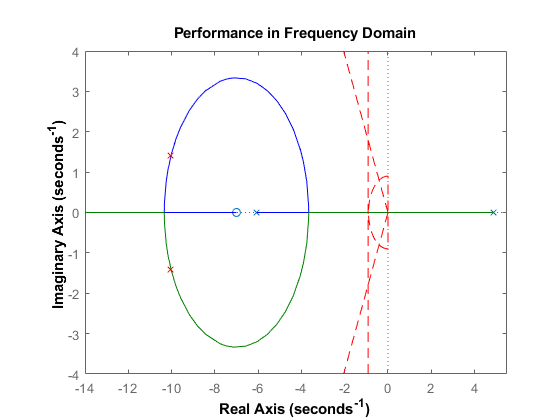

%L is the length
%angle is alpha
clc;

clear;
clf;

-log(5/100)

%%% tf shit %%%
s = tf('s');
sys = tf(1, [1/12 0.1 -9.82/4])
Ti = 1;
Td = 1/7;
Kp = 11;
Kpi = 1 + 1/(Ti*s);
Kpd = 1 + Td*s;
Kpid = 1 + 1/(Ti*s) + Td*s;

rlocus(Kpd * sys)
hold on
K = Kp * Kpd;
G = (K * sys) / (1 + K * sys)
[p,z] = pzmap(G)
%po = [complex(p(2), 0) complex(p(5), 0) complex(p(6), 0)];
plot(p(2:3),'rx')

syms x2 y2 L alpha x y x3 tr ts sigma wn p1 p2 p3 p4
x = 0;
y= 0;
L = 40;
Mp = 20;
alpha = sqrt(((log(Mp/100)/-pi)^2)/(1+(log(Mp/100)/-pi)^2))

x2=-L*alpha;
y2=-L*cos(asin(alpha));
tr = 2;
wn = 1.8/tr;
ts = 5;
sigma = 4.6/ts; 
x3 = sigma;

plot([x x2],[y y2], '--', 'color', 'r')

plot([x x2],[y -y2], '--', 'color', 'r') 

plot([-x3 -x3],[-L/2 L/2], '--', 'color', 'r')

plot_arc(pi/2, 3*pi/2, 0,0, wn)
title('Performance in Frequency Domain','FontWeight','bold')
%legend('Overshoot1','Overshoot2', 'Settling time', 'Rise time');
xlabel('Real Axis','FontWeight','bold');
ylabel('Imaginary Axis','FontWeight','bold')
xlim([-14, 5.5])
ylim([-4, 4])

hold off




function P = plot_arc(a,b,h,k,r)
    % Plot a circular arc as a pie wedge.
    % a is start of arc in radians, 
    % b is end of arc in radians, 
    % (h,k) is the center of the circle.
    % r is the radius.
    % Try this:   plot_arc(pi/4,3*pi/4,9,-4,3)
    % Author:  Matt Fig
    t = linspace(a,b);
    x = r*cos(t) + h;
    y = r*sin(t) + k;
    x = [x h x(1)];
    y = [y k y(1)];
    %P = fill(x,y,'r');
    P = plot(x,y, '--', 'color', 'r');
    %axis([h-r-1 h+r+1 k-r-1 k+r+1]) 
    if ~nargout
        clear P
    end
end
